# Estimation of Ganymede's Aurora Emission

Hongyang Zhou hyzhou@umich.edu 01/10/2018

Here I follow the approach in [Payan et.al 2015] for a quick analysis on Ganymede's aurora emission.

## Physics

As Jovian and/or Ganymede magnetospheric plasma precipitate(s) into Ganymede’s neutral atmosphere, electrons collide with oxygen molecules and excite oxygen atoms according to the reaction of electron impact dissociative excitation


$$O_2 + e^- \rightarrow O^\ast + O + e^- \rightarrow O + h\nu + O + e^- $$


Brightness dependencies:

- the number density of electrons $(n_e)$ with energies greater than 14.3 eV penetrating in a column of neutral atmosphere at Ganymede;

- the atmospheric column density of molecular oxygen at Ganymede, $N(O_2)$;

- the collisional excitation rate of oxygen molecules by electrons $C(T_e)$, and thus the electron temperatures $(T_e)$.

Qualitative relation:

- the larger the electron number density, the larger the number of oxygen molecules excited, and therefore the brighter the aurora;

- the larger the atmospheric column density of molecular oxygen, the larger the number of oxygen molecules that may be excited by penetrating electrons,and therefore the larger the auroral brightness;

- the larger the collisional excitation rate, the more efficient the reaction of electron impact dissociative excitation of $O_2$, and therefore the brighter the aurora. The rate is directly related to energy, but it doesn't mean that the higher energy you have, the larger rate it is.

## Parameters

kB = 1.38064852e-23; % [m^2*kg*s^{-2}*K^{-1}]
q  = 1.602e-19;      % [C]
me = 9.10938356e-31; % [kg]
mp = 1.6726219e-27;  % [kg]

a0 = 5.29e-9; % [cm], Bohr's radius

Ethres = 14.3; % [eV]

% cross section from lab experiments, [Kanik et al., 2003]
T = readtable('crosssection.csv','Delimiter',',',...
   'TreatAsEmpty',{'.','NA',''},'Format','%f%f%f%f');

Te = T.Energy; % [eV]
sigma = T.CrossSection1356 *1e-18; % [cm^2]

The efficiency of the reaction is characterized by a collisional excitation rate

$C(T_e) \approx 8.0104\times 10^{-8} \frac{\sigma(T_e)k T_e}{\pi {a_0}^2 \sqrt{k T_e}}e^{-\frac{E_{thres}}{k T_e}}$,

where

$\sigma(T_e)$ is the cross section of electron impact dissociation of $O_2 (cm^{-2})$which depends on the

impacting electron temperature $Te (eV)$. The relation is obtained from [Kanik et al., 2003] in the energy range $(14.3,600)eV$.

$E_{thres}$ is the transition threshold energy, $E_{thres} = 14.3 eV$, and

$a_0 = 5.29\times 10^{-9} cm$ is the Bohr's radius.

## Collisional Excitation Rate

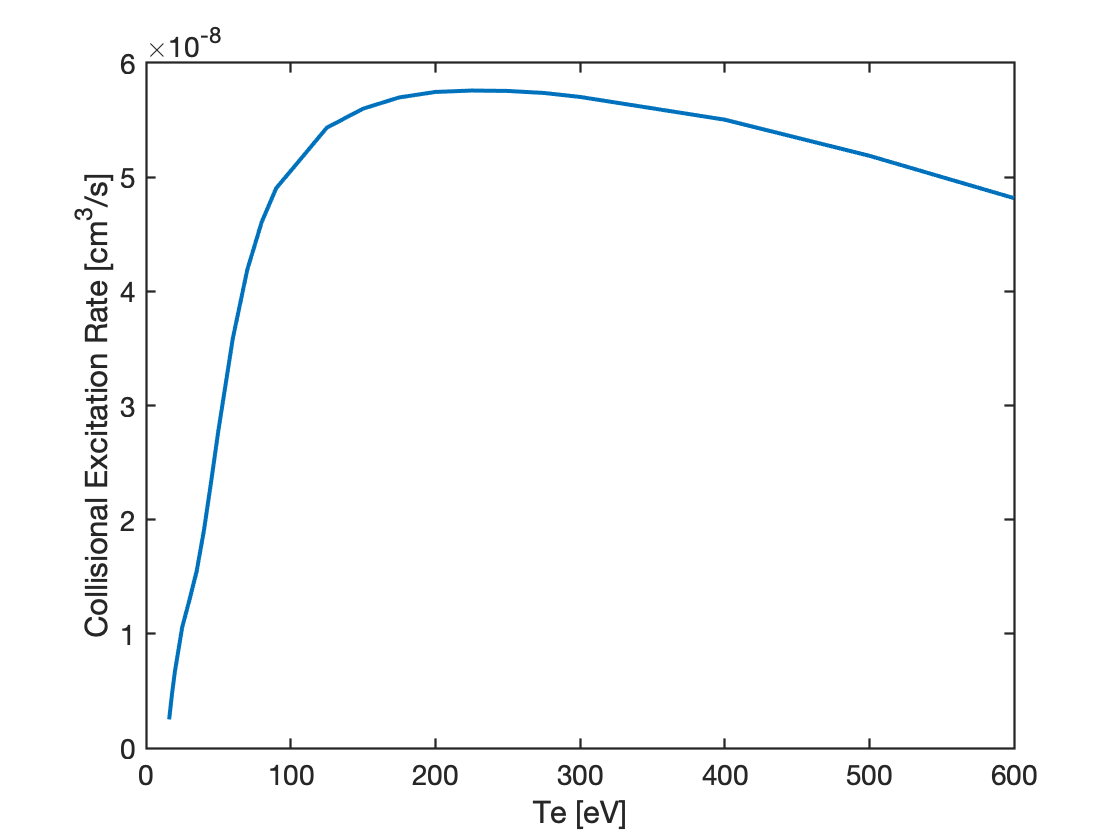

% The minimum electron speed required to excite O2
vMin = sqrt(Ethres*q*2/me)/1e3; % [km/s]

% Collisional excitation rate of oxygen
C = (8.0104e-8)*sigma.*Te./(pi*a0^2.*sqrt(Te)).*exp(-Ethres./Te);

figure
plot(Te,C,'LineWidth',2)
xlabel('Te [eV]'); ylabel('Collisional Excitation Rate [cm^{3}/s]')
set(gca,'FontSize',14,'LineWidth',1.1)

## Brightness Estimation

The brightness in $[R]$, or $[10^6/4\pi \  \text{photons}\ {cm}^{-2} s^{-1} sr^{-1}]$, is given by 

$B \approx 10^{-6} \times \int n_e(s)\times C(T_e,s)\times n(O_2, s)ds$,

where it integrates along the radial direction. I would assume they are integrating from the surface of the moon to the top of the ionosphere, but the height in radial direction they use in the paper is not mentioned.

As a further approximation, 

$B\approx 10^{-6}\times \bar{n_e}\times \bar{C}(T_e) \times N(O_2)$,

assuming omnidirectionally emission in $4\pi$space, where

$\bar{n_e}$ is the average value of electron number density, $[{cm}^{-3}]$, 

$C(T_e)$ is the average value of the electron collisional excitation rate, $[{cm}^3 s^{-1}]$,  and

$N(O_2)$ is the atmospheric column density of molecular oxygen at Ganymede, $[{cm}^{-2}]$.

$\bar{n_e}$ and $T_e$ are obtained directly from simulation.

$N(O_2)$ in the polar regions $\sim 3.74\times 10^{14} {cm}^{-2}$,

in the closed field line regions $\sim 5\times10^{14} {cm}^{-2}$.

The molecular oxygen column density used in their model is about 50 times smaller then these two numbers. They claim it is due to uncertainties, but I think not.

Note that for the electron number density, we should only consider those with an energy larger than the excitation threshold! However, if we are not dealing with a particle model, then there is only one value at one location, so we can't tell how many particles are within the range.

From [Eviator et.al 2001], a two regions atmosphere model is applied, for the inner region the Bates atmosphere model is used, and for the outer exosphere region a coronal model is applied for $O_2$ estimation:


$$n_{O_2}(r)=\begin{cases}
n_{O_2}(1) \Big[ \frac{1-\eta}{e^{\tau \Phi} - \eta}\Big]^{1+\Gamma} e^{\tau\Phi},&\ r \le r_c \\
n_{O_2}(r_c)\Big( \frac{1+r_c}{1+r}\Big)^2 \exp{\Big[-\frac{r-r_c}{H(r_c)}\Big]},&\ r>r_c
\end{cases}$$


where the surface $O_2$ density is taken to be $n_{O_2}(1) = 1\times10^8 cm^{-3}$, the transition radius $r_c = 1.38R_G$. The temperature gradient scale $\eta$ is


$$\eta = \frac{T_{inf} - T_0}{T_{inf}},$$


where $T_{0} = 0.011eV$ is the surface temperature, and $T_{inf} = 0.0086eV$is the exosphere temperature.


$$\tau = \frac{1}{\eta T_{inf}}\frac{dT}{dr}$$


is taken to be $10^{-4} cm^{-1}$, and the gravipotential radial distance


$$\Phi =R_G\Big( \frac{r-1}{r}\Big),$$


the scale height is 

$H(r) = \frac{T(r)}{mg(r)}$,

and the ratio of the temperature gradient to the scale height is given by 

$\Gamma = \frac{1}{\tau H_2(1)}$ = 0.4851

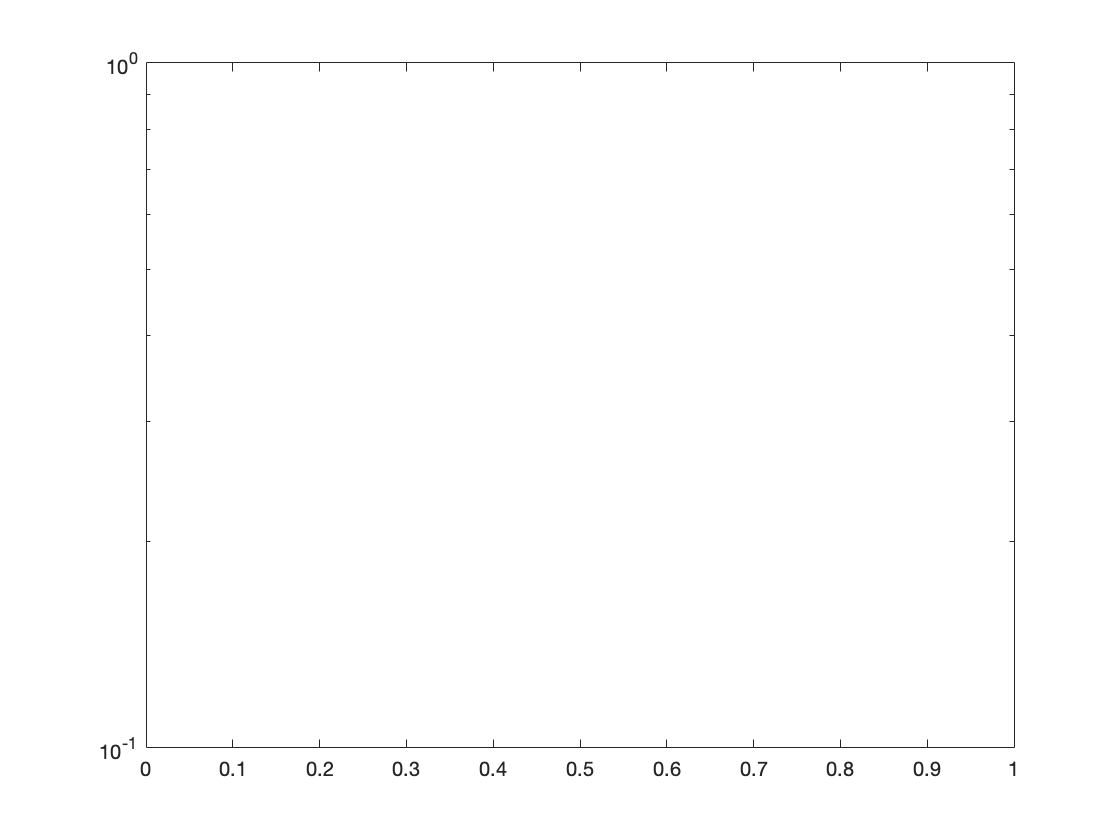

RG = 2634e3; %[m]
r = linspace(1,2.4,50);
Gamma = 0.4851;
nO2_1 = 1e8;
rc = 1.38;
Phi = RG * (r-1)./r; 
tau = 1e-4*1e2; % [cm^{-1}]
Tinf = 0.086; T0 = 0.011; % [eV]
eta = (Tinf - T0) / Tinf;
H = 125e3/RG;


nO2 = nO2_1*(((1 - eta)./(exp(tau*Phi) - eta)).^(1+Gamma).*exp(tau*Phi));

nO2 = (r<=rc) .*nO2 + (r>rc) .* nO2(find(r<=rc,1,'last')) .* ...
    ((1+rc)./(1+r)).^2 .* exp(-(r-rc)./H);

figure
semilogy(r,nO2)

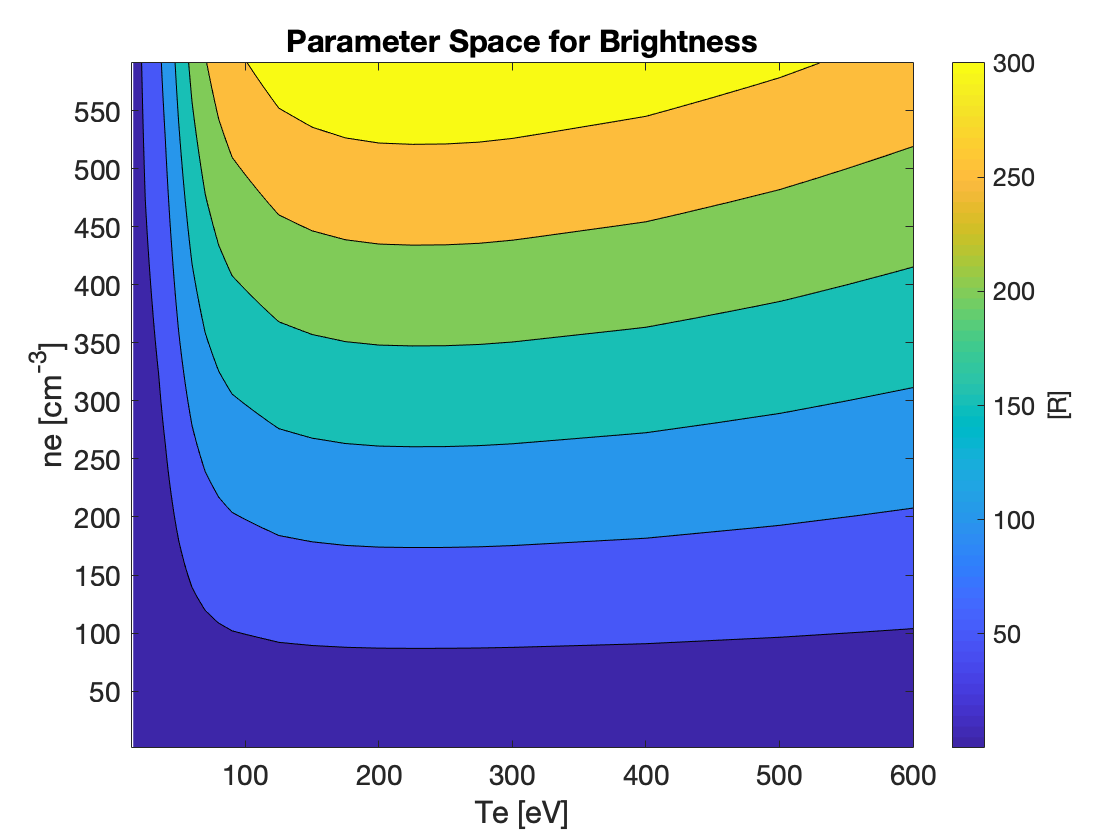

NO2 = 10000000000000; % [cm^{-2}]
ne = 1:10:600; %[cc]
B = (1e-6)*C*ne*NO2; % [R]
%B = (1e-6)*ne*nanmean(C)*3.74e14; % [R]
figure
[neMesh, TeMesh] = meshgrid(ne,Te); 
contourf(TeMesh,neMesh,B); h = colorbar;
ylabel(h,'[R]')
xlabel('Te [eV]'); ylabel('ne [cm^{-3}]');
title('Parameter Space for Brightness')
set(gca,'FontSize',14);

Comparing with [Eviator et.al. 2001], I plot the following four lines with four different electron densities, same as the values used in that paper. Note that the molecular oxygen model is different.

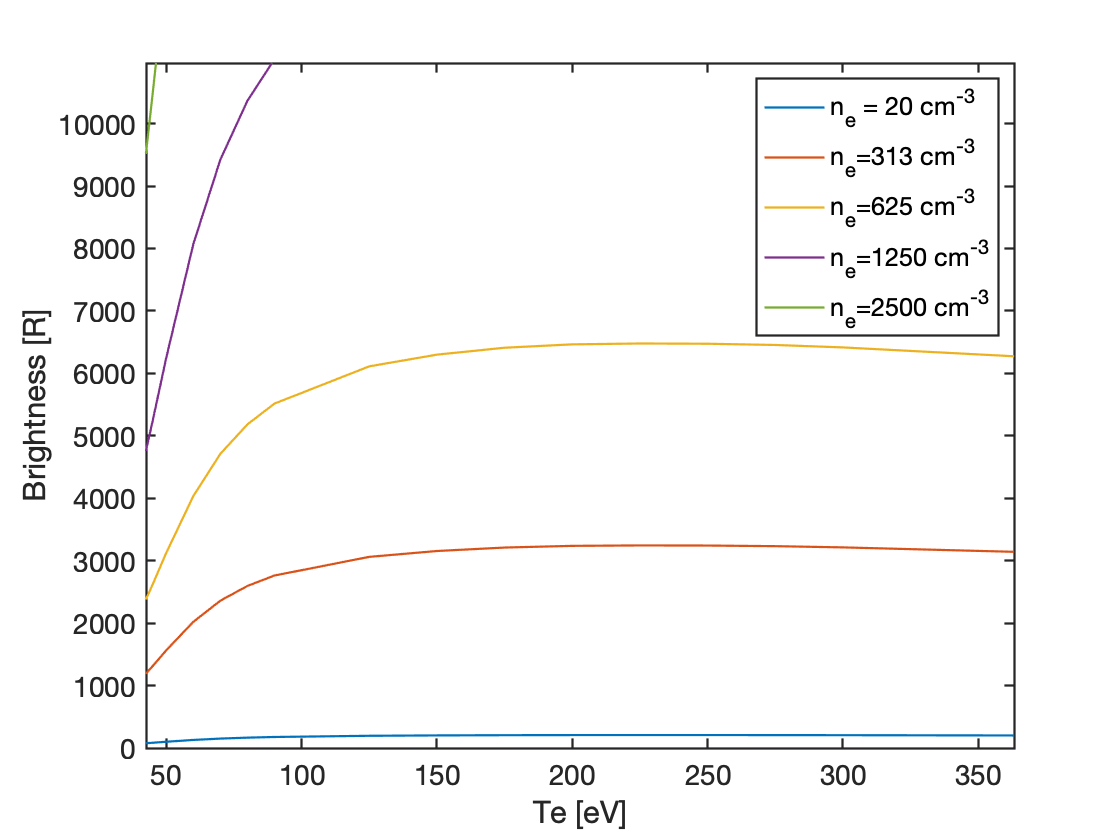

ne = [20,313,625,1250,2500]; % [cc]
B = (1e-6)*C*ne*1.8e14; % [R]
figure
plot(Te,B(:,:),'LineWidth',1.1)
xlabel('Te [eV]'); ylabel('Brightness [R]');
legend({'n_e = 20 cm^{-3}','n_e=313 cm^{-3}','n_e=625 cm^{-3}',...
    'n_e=1250 cm^{-3}','n_e=2500 cm^{-3}'})
set(gca,'FontSize',14,'LineWidth',1.1)

I notice some issues with our current model. In their multifluid model, they predict bulk energy values in the keV range for the magnetospheric plasma electrons and in the tens of keV range for the Jovian plasma electrons. We dont't have such high energy electrons in our MHD-EPIC simulations.

Thermal velocity is not the same as bulk velocity: bulk energy is related to thermal velocity, not bulk velocity!

Pe = 2; % [nPa]
ne = 595; % [amu/cc]
Te = Pe/ne/q/1e15; % [eV]

What I have in my plots are energy flux densities in $[W m^{-2}]$.


$$flux = \frac{1}{2} m_e n_e {v_e}^2 v_{\parallel}$$


upstream Jovian electrons has temperature of


$$T_{e,up} = \frac{P_{e,up}}{nk_B} = \frac{0.2 [nPa]}{4\times10^{-6}k_B} = 3.62\times 10^{6} [K] \approx 312 [eV]$$


upstream Jovian ion has temperature of


$$T_{i,up} = \frac{P_{i,up}}{nk_B} = \frac{3.6 [nPa]}{4\times10^{-6}k_B} =  5618 [eV]$$


surface electrons has temperature of 20 [eV].

Teup = 0.2/4/q/1e15; % [eV]
Tiup = 3.6/4/q/1e15; % [eV]